#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# A3 Solutions

## Problem 1

clear all
close all
clc

Load the image data and measure the matrix size

load BMEA3
[Nr, Nc] = size(IMG50);
fprintf('Image size is %d (rows) x %d (columns)',Nr,Nc)

Image size is 128 (rows) x 128 (columns)

FOV = 16; %cm -- given in the assignment

In order to work in spatial dimensions, we can define and index space for each direction of the image matrix. Because the image matrix and FOV are square, one index will do, but we'll make two to be thorough.

Define the indices at the middle of each row/column.

dr = FOV/Nr; dc = FOV/Nc;
fprintf('Each row/column is %.3f / %.3f cm wide',dr,dc)

Each row/column is 0.125 / 0.125 cm wide

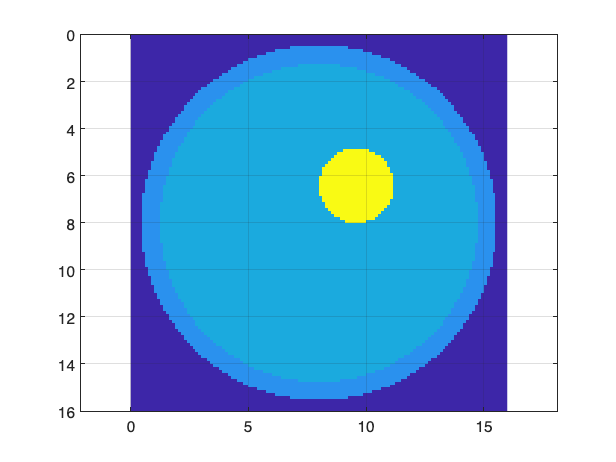

r_index = (dr/2:dr:FOV-dr/2); 
c_index = r_index;
imagesc(c_index,r_index,IMG50), axis('equal') % note c,r index order

Define the duration of the X-Ray pulse and the area of each detector

delt = 0.1; % 100 ms or 0.1 secon
det_area = 1*dr; % 1 cm thick x dr (cm) = area of each detector in cm^2 

The emitted photon fluency is $600 \times 10^8$ photons/cm^2/s.

fluency = 600e8; % photons/cm^2/s

Then, the number of photons emitted per row is 

N0 = fluency*delt*det_area; % photons emitted per row

and because the X-Ray beam is monoenergetic, its intensity is simply proportional to $N_0$  

Therefore, the number of photons is attenuated along its path according to 


$$N(y) = N_0 \exp\left[-\int \limits_0^{16} dx\, \mu (x,y)\right]$$


where $y$ indicates the postion of the row through which the X-Ray beam is traveling.

We can compute the intergral using trapezoidal integration

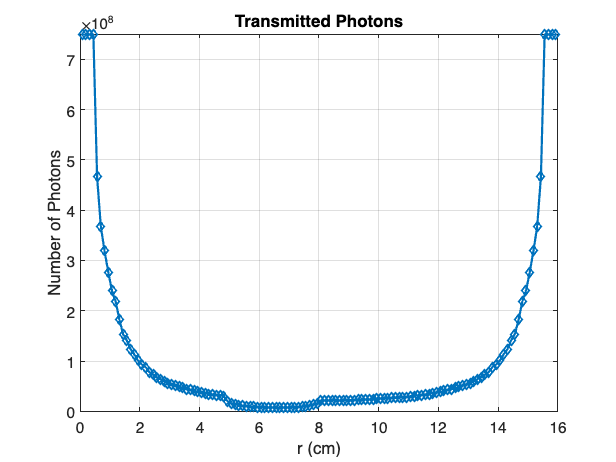

int_dx = trapz(c_index, IMG50,2);% integrate along each row
N = N0*exp(-int_dx); %page 16-17, number of photons that reach the detectors

figure('Name','A3:Problem 1a')

plot(c_index,N,'d-')
axis([0 16 0 N0])
title('Transmitted Photons')
xlabel('r (cm)')
ylabel('Number of Photons')

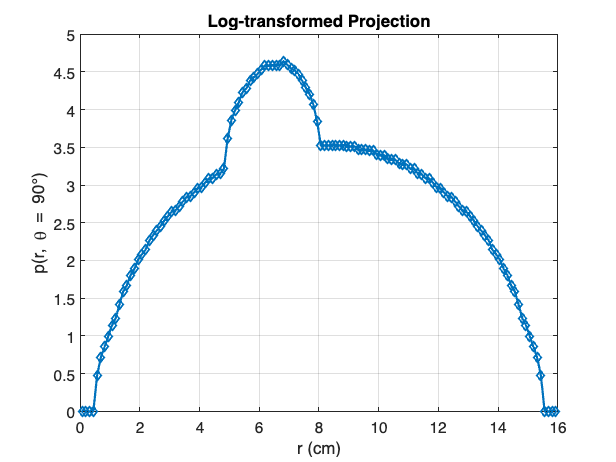

figure('Name','A3:Problem 1b')
plot(c_index,-log(N/N0),'d-') % page 36
title('Log-transformed Projection')
xlabel('r (cm)')
ylabel('p(r, \theta = 90°)')
axis([0 16 0 5])

## problem 2

demonstrate the Projection Slice Theorem References page 39 from text

clear all
close all
load BMEA3

Same starting steps as in problem 1. Load the image data and measure the matrix size

load BMEA3
[Nr, Nc] = size(IMG50);
fprintf('Image size is %d (rows) x %d (columns)',Nr,Nc)

Image size is 128 (rows) x 128 (columns)

FOV = 16; %cm -- given in the assignment

In order to work in spatial dimensions, we can define and index space for each direction of the image matrix. Because the image matrix and FOV are square, one index will do, but we'll make two to be thorough.

Define the indices at the middle of each row/column.

dr = FOV/Nr; dc = FOV/Nc;
fprintf('Each row/column is %.3f / %.3f cm wide',dr,dc)

Each row/column is 0.125 / 0.125 cm wide

r_index = (dr/2:dr:FOV-dr/2); 
c_index = r_index;


Projection Slice Theorem states that the FT of a projection (p) through an image (f) at angle theta (see Fig 3.5) is equal to a slice through the 2D fourier transform of image (F). That is, $P(\theta) = \mathcal{F}\left[p(\theta)\right] = F(k_x,k_y)$ where $k_x = k \cos(\theta)$, $k_y = k \sin(\theta)$ and $k = \sqrt{k_x^2+k_y^2}$. see Eq 3.11-3.15.

To demonstrate this theorem, consider a projection through image IMG50 at angle $\theta = 0$ degrees -- i.e., projecting along the columns. To compute this, we integrate the signal along each column. We can use trapazoidal approximation for integration

% projection in vertical (theta = 0°) direction is dimension 1
p_0 = trapz(c_index, IMG50, 1);

%We now take the fft of this profile.
P_0 = fftshift(abs(fft(p_0))); %eq. 3.13 from text

figure('Name','A3: Problem 2. Projection at theta = 0°')
semilogy(P_0,'r-')
hold on

Now let's compare this to the slice through the 2DFT of IMG50. Remember: 2DFT of f(x,y) = F = F(kx,ky). At $\theta = 0$, the slice in F corresponds exactly to the center row. That is, the row where $k_y = 0$, which is the 65th row for a 128 point FT.

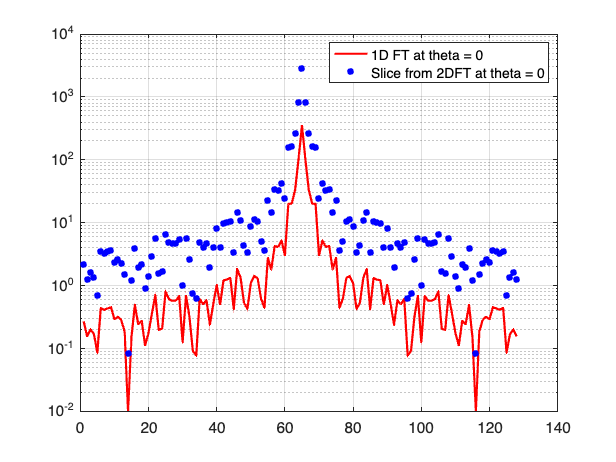

F = fftshift(abs(fft2(IMG50)));
F_0 = F(65,:);
semilogy(F_0,'b*')
legend('1D FT at theta = 0', 'Slice from 2DFT at theta = 0')

The shapes look the same, but the scaling is different. Recall that the fft in MATLAB does not include multiplication by the sample period, but effect is incorported in the integration along the projection line. We can either multiply this term when doing FTs or divide out from the integration. Here, we will include it in the FTs to be most general.

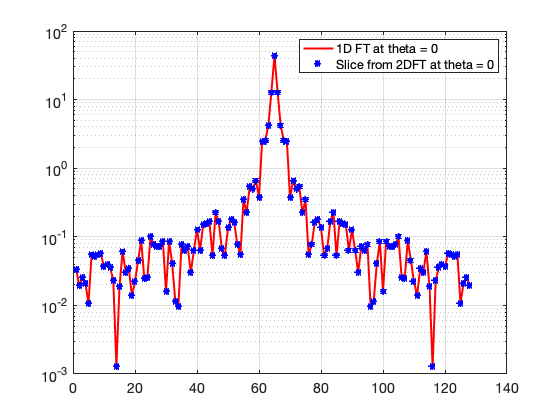

dy = diff(c_index(1:2)); % sample period in the direction of projection
dx = diff(r_index(1:2)); % sample period in the x direction

P_0 = fftshift(abs(dy*fft(p_0))); % recalculated FT

figure('Name','A3: Problem 2. Projection at theta = 0°, 2nd try')
semilogy(P_0,'r-')
hold on
%multiply by both sampling periods for a 2D FT
F = dx*dy*fftshift(abs(fft2(IMG50)));
F_0 = F(65,:);
semilogy(F_0,'b*')
legend('1D FT at theta = 0', 'Slice from 2DFT at theta = 0')

Now they agree, and the Projection Slice Theorem is demonstrated.

To reconstruct the full image from a sinogram without backprojecting we can perform 1D FT on each projection in the sinogram, to produce a radial sampling of F(kx,ky). We then need to "grid" these samples -- i.e., interpolate the radial samples onto a Cartesian grid -- then inverse 2D FT to get the reconstructed image. Because there is no backprojection process, there is no filtering to correct for the blurring imparted by backprojecting.

## problem 3, point spread function

clear all
close all
clc

% create an image with a single point
N = 129;
IMGx = zeros(N,N);
IMGx(floor(N/2)+1,floor(N/2)+1) = 1;
Nspace = [8,16,32,64,128,256];

% start with the Ram-Lak filter
fprintf('A3: Problem 3. Ram-Lak, varied # of projections')

A3: Problem 3. Ram-Lak, varied # of projections

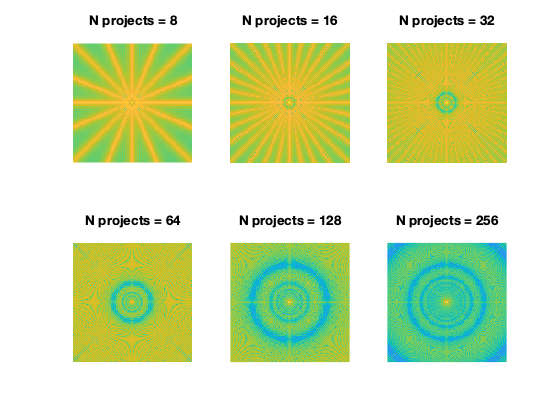

figure, grid off
for kt = 6:-1:1
    Ns = Nspace(kt);
    inc = 180/Ns;
    theta = 0:inc:180-inc;
    g = radon(IMGx,theta);
    Ix = iradon(g,theta,'linear','Ram-Lak')';
    subplot(2,3,kt)
    imagesc(log10(abs(Ix)),[-10 0]), axis('equal')%, colorbar
    title(['N projects = ',num2str(Ns)])
    axis('off')
    % pause
    PSF(:,kt) = sum(Ix);
end

For small number of projection angles, we can see the estimated PSF is dominated by radial spokes with high magnitude. These result in radial streaks in the reconstructed image and are not generally useful. As the number of projections gets larger, we see a circular region without the spokes form. The diameter of this region in points is $\frac{2}{\pi}N_\mathrm{projections}$. 

If we have a cicularly symmetric image with diameter $L$, then $N_\mathrm{projections} = (\pi/2)\frac{L}{\Delta x}$ will avoid the spoke artefacts due toradial aliasing. (Although this is a simplified analysis.) This region is not perfectly flat with a deltaunction at the center though, because finite sampling of the projection also leads to finite amounts of aliasing and blurring. 


fprintf('A3: Problem 3. Ram-Lak, demo Ns = pi/2*Nx')

A3: Problem 3. Ram-Lak, demo Ns = pi/2*Nx

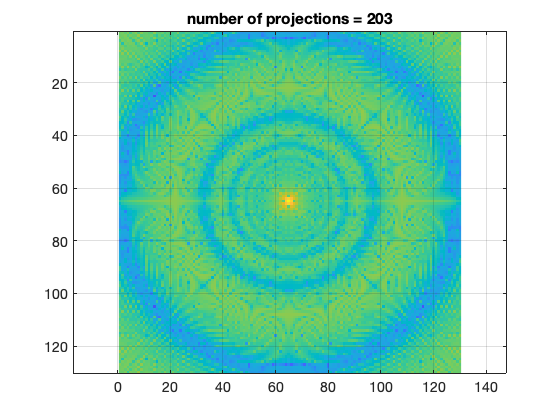

figure, grid off
Ns = round(N*pi/2);
inc = 180/Ns;
theta = 0:inc:180-inc;
g = radon(IMGx,theta);
Ix = iradon(g,theta,'linear','Ram-Lak')';
imagesc(log10(abs(Ix)),[-10 0]), axis('equal')% colorbar
title(['number of projections = ',num2str(Ns)])

fprintf('A3: Problem 3. Hamming, varied # of projections')

A3: Problem 3. Hamming, varied # of projections

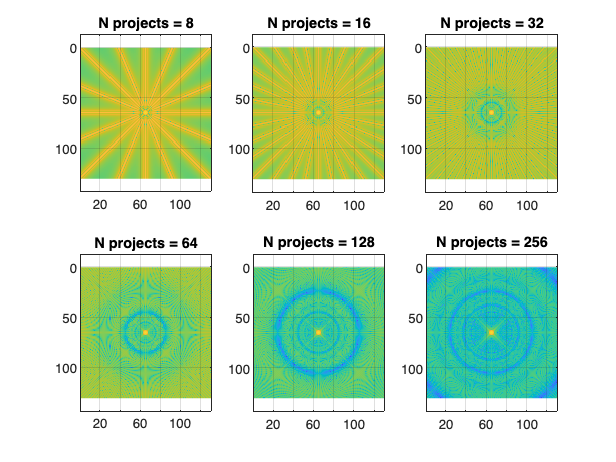

figure, grid off
for kt = 1:6
    Ns = Nspace(kt);
    inc = 180/Ns;
    theta = 0:inc:180-inc;
    g = radon(IMGx,theta);
    Ix = iradon(g,theta,'linear','Hamming')';
    subplot(2,3,kt)
    imagesc(log10(abs(Ix)),[-10 0]), axis('equal')% colorbar
    title(['N projects = ',num2str(Ns)])
    % pause
    PSF(:,kt) = sum(Ix);
end

The Hamming filter does not change the angular sampling requirements, which makes sense because the filter is only acting in the radial direction. The center of the PSF is slightly wider though, reflecting the increased smoothing that comes with suppression of high frequencies start with the unfiltered backprojection follows the same pattern except that the central region that grows with N_projections is relatively flat, which causes large blurring effect seen in unfiltered BP images


fprintf('A3: Problem 3. Unfiltered, varied # of projections')

A3: Problem 3. Unfiltered, varied # of projections

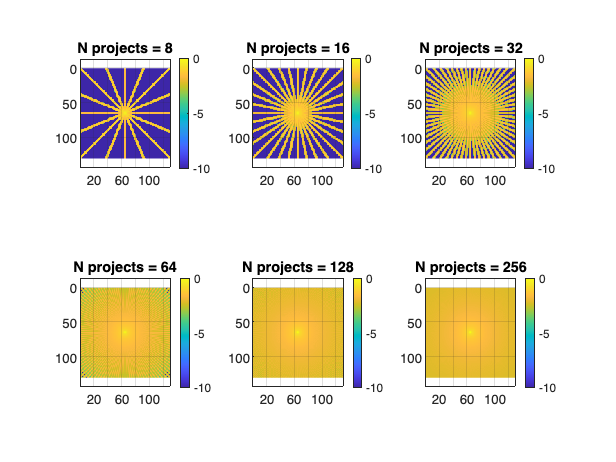

figure, grid off
for kt = 1:6
    Ns = Nspace(kt);
    inc = 180/Ns;
    theta = 0:inc:180-inc;
    g = radon(IMGx,theta);
    Ix = iradon(g,theta,'linear','none')';
    subplot(2,3,kt)
    imagesc(log10(abs(Ix)),[-10 0]), axis('equal'), colorbar
    title(['N projects = ',num2str(Ns)])
    % pause
    PSF(:,kt) = sum(Ix);
end

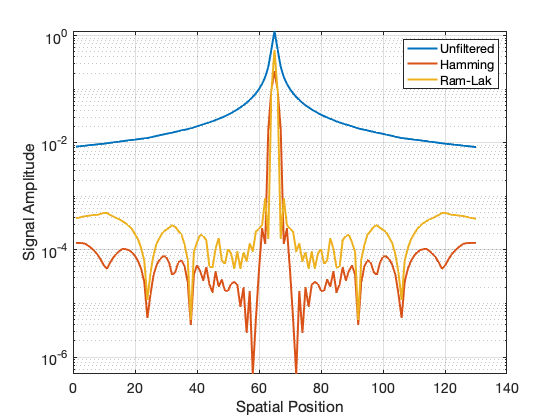


% In the unfiltered case, the 


figure('Name','A3: Problem 3. Profiles through PSF')
Ix = iradon(g,theta,'none')';
semilogy(abs(Ix(65,:))); hold on
Ix = iradon(g,theta,'Hamming')';
semilogy(abs(Ix(65,:))); hold on
Ix = iradon(g,theta,'Ram-Lak')';
semilogx(abs(Ix(65,:))); hold on
legend('Unfiltered','Hamming','Ram-Lak')
ylabel('Signal Amplitude')
xlabel('Spatial Position')

Looking at the images and the profiles we can see that it does, however, reduce the magnitude of the side lobes at the expense of slightly broadening the central lobe. Hence, the Hamming filter will impart some blurring, but will reduce ringing aretfact that may be observed in a Ram-Lak reconstructed image.

## problem 4

% 4a 
% definition of the CT signal measure in Hounsfield units is 
% h = 1000 x (µ_tissue-µ_water)/µ_water.
% From NIST site
% density of bone = 1.92 g/cm^3 
% density of water = 1.00 g/cm^3
% at 40 keV, µ_bone = 0.666 (cm^2/g) x 1.92 (g/cm^3) = 1.28 cm^-1
% at 80 keV, µ_water = 0.268 (cm^2/g) x 1.00 (g/cm^3) = 0.268 cm^-1
ub40 = 1.28; uw40 = 0.268;
h_bone_40 = 1000*(ub40-uw40)/uw40
% = 3776 HU

% at 40 keV, µ_bone = 0.223 (cm^2/g) x 1.92 (g/cm^3) = 0.428 cm^-1
% at 80 keV, µ_water = 0.184 (cm^2/g) x 1.00 (g/cm^3) = 0.184 cm^-1
ub80 = 0.428; uw80 = 0.184;
h_bone_80 = 1000*(ub80-uw80)/uw80
% = 1326 HU


4b

Three types of noise affect X-ray CT: quantum (or statistical), electronic, quantization. In most cases, the quantum noise dominates over the other two. This makes sense because we generally want to use the **minimal X-ray dose**, and the relative level of** quantum noise increases** with d**ecreased dose.**

4c

Doubling the X-ray tube voltage will double the** max photon energy** and almost double (depending on the starting voltage) the **mean energ**y. Higher energy photons means l**ower linear attentuation coefficients** and less relative contribution due to photoelectric interactions. The effect of these changes on image quality will be: 1) **lower contrast due to the lower contribution of PE interactions,** 2)** increased SNR **due to more photons reaching the detectors thereby reducing the relative quantum noise. Whether or not the effective contrast to noise ratio increases or decreases depends on the tissues and energies involved. 

4d

Doubling the X-ray tube current doubles the photon fluence rate, which will result in** increase signal to noise ratio** (at the expense of also increasing the dose, although that is not a factor of image quality). The higher fluence rate will also allow for **a shorter exposure time,** which may result in **reduced motion artefac**t in some cases.

4e

As you can see from Table 3.1 in the text, a head CT has a much greater volumetric absorbed dose than does an abdominal CT, but a head is smaller and, more importantly, in converting from dose to effective dose, the weighting factor for brain (0.01) is much smaller than for abdominal tissues (stomach: 0.12, colon: 0.12, ...) thus the conversion factor is approximately 6x smaller for the head CT.